### ACO VS  AHACO(adaptive heuristic )

clc;clear;clf
global color_map
color_map = [1 1 1;...  % 1-白色-空地
    0 0 0;...  % 2-黑色-障碍物
    0 1 1;...  % 3-青蓝色-start_pos
    1 0 0;...  % 4-红色-goal_pos(maybe many)
    0 1 0;...  % 5-绿色-path
    0 0 1;...  % 6-蓝色-
    1 1 0;...  % 7-黄色
    1 0 1];...  % 8-品红色
%set param
row_map = 20;
column_map = 20;
obstacle_rate = 0.3;
%construct
% field =[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 1 0 0 0 1 1 1 0 0 0 0 0 0 1 1 1 0 0;
%      0 0 0 0 0 0 1 1 1 0 0 0 0 0 0 1 1 1 0 0;
%      0 0 0 0 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;
%      0 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
%      0 1 1 1 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 1 1 1 0 1 0 1 1 0 0 0 0 0 0;
%      0 1 1 1 0 0 0 0 0 0 1 0 1 1 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 1 1 0 1 1 1 1 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 0 0 0 0 1 1 1 0 1 1 1 0 0;
%      0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0;
%      0 0 1 1 0 0 0 0 0 0 1 1 1 1 1 1 1 1 0 0;
%      0 0 1 1 0 0 1 1 1 0 1 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 1 1 1 0 1 0 0 0 0 0 0 1 1 0; 
%      0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 1 1 0;
%      0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0;
%      0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
[field,color_map] = constructMap(row_map,column_map,obstacle_rate);
% field(field == 1) = 2;
% field(field == 0) = 1;
% indirect start_pos and goal_pos
% field = load('field.mat');
% field = field.field;
start_pos = 19;
goal_pos = row_map*column_map-18;
% goal_pos = 64-4;
field(start_pos) = 3;
field(goal_pos) = 4;
field_copy = field;
%----cal ACA
% tic
% [dist_best1, path_best1, per_iter_best1,per_iter_avg1] = ACA(field,start_pos,goal_pos);
% toc

%----cal improvedEtaACA
tic
[dist_best2, path_best2, per_iter_best2,per_iter_avg2] = improvedEtaACA(field,start_pos,goal_pos);
toc

历时 1.454431 秒。


%%draw pic
% figure(1)
% colormap(color_map);
% 
% fisrt_inf_ind = find(isinf(path_best1(1,:)),1);
% path_best1 = path_best1(1:fisrt_inf_ind-1);
% 
% image(1.5,1.5,field);
% hold on;
% grid on;
% set(gca,'gridline','-','GridColor','k','LineWidth',2,'GridAlpha',1);
% set(gca,'XTick',1:column_map+1,'YTick',1:row_map+1);
% set(gca,'XAxisLocation','top')
% axis image
% for i = 1:length(path_best1)-1
%     [coord1_x,coord1_y] = ind2sub([row_map,column_map],path_best1(i));
%     [coord2_x,coord2_y] = ind2sub([row_map,column_map],path_best1(i+1));
%     plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'o-', 'linewidth', 1.1,'linestyle','-','Color','b','markerfacecolor', 'b')
%     %这里的coord1_x应该是对应的y
% end
% hold on
% 
% colormap(color_map);
% 
% fisrt_inf_ind = find(isinf(path_best2(1,:)),1);
% path_best2 = path_best2(1:fisrt_inf_ind-1);
% 
% grid on;
% set(gca,'gridline','-','GridColor','k','LineWidth',2,'GridAlpha',1);
% set(gca,'XTick',1:column_map+1,'YTick',1:row_map+1);
% set(gca,'XAxisLocation','top')
% axis image
% hold on
% for i = 1:length(path_best2)-1
%     [coord1_x,coord1_y] = ind2sub([row_map,column_map],path_best2(i));
%     [coord2_x,coord2_y] = ind2sub([row_map,column_map],path_best2(i+1));
%     plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'o--', 'linewidth', 1.1, 'linestyle','--','Color','m','markerfacecolor', 'm');
%     %这里的coord1_x应该是对应的y
% end
% hold off;
% title('Best Path of ACO and AHACO ');
% set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')


numb_turn_org = 0;
numb_turn_remove = 0;
for j = 1:length(path_best2)-2
    ind1 = path_best2(j);
    ind2 = path_best2(j+1);
    ind3 = path_best2(j+2);
    [ind1_sub(1),ind1_sub(2)] = ind2sub([20,20],ind1);
    [ind2_sub(1),ind2_sub(2)] = ind2sub([20,20],ind2);
    [ind3_sub(1),ind3_sub(2)] = ind2sub([20,20],ind3);
    if (ind3_sub(2)-ind2_sub(2))/(ind3_sub(1)-ind2_sub(1)) ~= ...
        (ind1_sub(2)-ind2_sub(2))/(ind1_sub(1)-ind2_sub(1))
        numb_turn_org = numb_turn_org+1;
    end
end

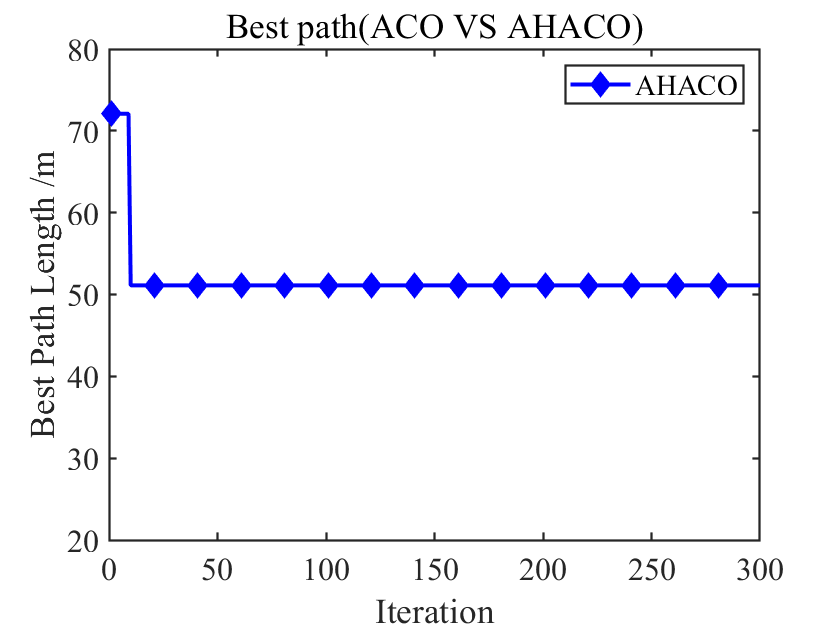

figure(2)
% subplot(1,2,1)
% 平均值会出现一些inf不好比较
maker_idx = 1:20:length(per_iter_avg2);

% plot(per_iter_best1, 'or-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'r','MarkerIndices',maker_idx)
% hold on
plot(per_iter_best2, 'db-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'b','MarkerIndices',maker_idx)
xlabel('Iteration')
ylabel('Best Path Length /m');
% legend('ACO','AHACO');
legend('AHACO');
axis([0, 300, 20 80])
set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')
title('Best path(ACO VS AHACO)');


% subplot(1,2,2)
% maker_idx = 1:20:length(per_iter_avg2);
% 
% plot(per_iter_avg1, 'or-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'r','MarkerIndices',maker_idx)
% hold on
% plot(per_iter_avg2, 'db-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'b','MarkerIndices',maker_idx)
% xlabel('Iteration')
% ylabel('Average Path Length /m');
% legend('ACO','AHACO');
% axis([0, 300, 20 80])
% set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')
% title('Avgerage path(ACO VS AHACO)');

### ACO VS APACO(adaptive state transition probability)

clc;clear;clf
global color_map
color_map = [1 1 1;...  % 1-白色-空地
    0 0 0;...  % 2-黑色-障碍物
    0 1 1;...  % 3-青蓝色-start_pos
    1 0 0;...  % 4-红色-goal_pos(maybe many)
    0 1 0;...  % 5-绿色-path
    0 0 1;...  % 6-蓝色-
    1 1 0;...  % 7-黄色
    1 0 1];...  % 8-品红色
%set param
row_map = 20;
column_map = 20;
obstacle_rate = 0.1;
% %construct
% field =[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 1 0 0 0 1 1 1 0 0 0 0 0 0 1 1 1 0 0;
%      0 0 0 0 0 0 1 1 1 0 0 0 0 0 0 1 1 1 0 0;
%      0 0 0 0 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;
%      0 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
%      0 1 1 1 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 1 1 1 0 1 0 1 1 0 0 0 0 0 0;
%      0 1 1 1 0 0 0 0 0 0 1 0 1 1 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 1 1 0 1 1 1 1 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 0 0 0 0 1 1 1 0 1 1 1 0 0;
%      0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0;
%      0 0 1 1 0 0 0 0 0 0 1 1 1 1 1 1 1 1 0 0;
%      0 0 1 1 0 0 1 1 1 0 1 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 1 1 1 0 1 0 0 0 0 0 0 1 1 0; 
%      0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 1 1 0;
%      0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0;
%      0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
[field,color_map] = constructMap(row_map,column_map,obstacle_rate);
% field(field == 1) = 2;
% field(field == 0) = 1;
% indirect start_pos and goal_pos
% field = load('field.mat');
% field = field.field;
start_pos = 19;
goal_pos = size(field,1)*size(field,2)-19;
% goal_pos = 64-4;
field(start_pos) = 3;
field(goal_pos) = 4;
field_copy = field;
% %----cal ACA
tic
[dist_best1, path_best1, per_iter_best1,per_iter_avg1] = ACA(field,start_pos,goal_pos);
toc

历时 25.154397 秒。



%----cal improvedProbACA
tic
[dist_best2, path_best2, per_iter_best2,per_iter_avg2] = improvedProbACAExp(field,start_pos,goal_pos);
toc

历时 11.695157 秒。


% %%draw pic
% figure(1)
% colormap(color_map);
% subplot(1,2,1)
% fisrt_inf_ind = find(isinf(path_best1(1,:)),1);
% path_best1 = path_best1(1:fisrt_inf_ind-1);
% field(path_best1(2:end-1)) = 5;
% image(1.5,1.5,field);
% hold on;
% grid on;
% set(gca,'gridline','-','GridColor','k','LineWidth',2,'GridAlpha',1);
% set(gca,'XTick',1:column_map+1,'YTick',1:row_map+1);
% set(gca,'XAxisLocation','top')
% axis image
% for i = 1:length(path_best1)-1
%     [coord1_x,coord1_y] = ind2sub([row_map,column_map],path_best1(i));
%     [coord2_x,coord2_y] = ind2sub([row_map,column_map],path_best1(i+1));
%     plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'ok-', 'linewidth', 1.1,'linestyle','-','Color','b','markerfacecolor', [36, 169, 225]/255)
%     %这里的coord1_x应该是对应的y
% end
% hold off;
% title('Best Path of ACO')
% 
% colormap(color_map);
% subplot(1,2,2)
% fisrt_inf_ind = find(isinf(path_best2(1,:)),1);
% path_best2 = path_best2(1:fisrt_inf_ind-1);
% field_copy(path_best2(2:end-1)) = 5;
% image(1.5,1.5,field_copy);
% grid on;
% set(gca,'gridline','-','GridColor','k','LineWidth',2,'GridAlpha',1);
% set(gca,'XTick',1:column_map+1,'YTick',1:row_map+1);
% set(gca,'XAxisLocation','top')
% axis image
% hold on
% for i = 1:length(path_best2)-1
%     [coord1_x,coord1_y] = ind2sub([row_map,column_map],path_best2(i));
%     [coord2_x,coord2_y] = ind2sub([row_map,column_map],path_best2(i+1));
%     plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'ok-', 'linewidth', 1.1, 'linestyle','-','Color','b','markerfacecolor', [29, 191, 151]/255);
%     %这里的coord1_x应该是对应的y
% end
% hold off;
% title('Best Path of APACO')

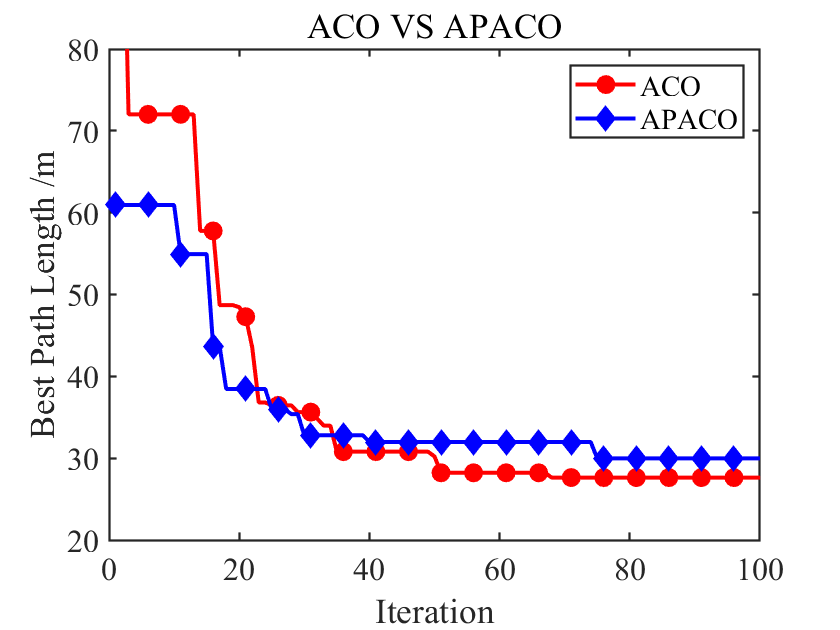

figure(2)
%平均值会出现一些inf不好比较
maker_idx = 1:5:length(per_iter_avg2);
% plot(per_iter_best1, 'or-', 'linewidth', 2, 'markersize',7.5,'MarkerEdgeColor',[0 0 0],'markerfacecolor', [36, 169, 225]/255,'MarkerIndices',maker_idx)
% hold on
% plot(per_iter_best2, 'db-', 'linewidth', 2, 'markersize',7.5,'MarkerEdgeColor',[0 0 0],'markerfacecolor', [29, 191, 151]/255,'MarkerIndices',maker_idx)
plot(per_iter_best1, 'or-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'r','MarkerIndices',maker_idx)
hold on
plot(per_iter_best2, 'db-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'b','MarkerIndices',maker_idx)
xlabel('Iteration')
ylabel('Best Path Length /m');
legend('ACO','APACO');
axis([0, 100, 20 80])
set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')
title('ACO VS APACO')


% subplot(122)
% maker_idx = 1:5:length(per_iter_avg2);
% plot(per_iter_avg2, 'ok-', 'linewidth', 1.1,'markersize',7.5, 'markerfacecolor', [36, 169, 225]/255,'MarkerIndices',maker_idx)
% hold on
% plot(per_iter_best2, 'dk-', 'linewidth', 1.1,'markersize',7.5, 'markerfacecolor', [29, 191, 151]/255,'MarkerIndices',maker_idx)
% xlabel('Iteration')
% ylabel('Path Length /m');
% legend('Average Length per Iteration','Best Length per Iteration');
% axis([0, 160, 20 120])
% set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')
% title('AHACO');  % 自适应启发函数的ACO

#### **计算转角次数**

numb_turn_org = 0;
numb_turn_prob = 0;
for j = 1:length(path_best1)-2
    ind1 = path_best1(j);
    ind2 = path_best1(j+1);
    ind3 = path_best1(j+2);
    [ind1_sub(1),ind1_sub(2)] = ind2sub([20,20],ind1);
    [ind2_sub(1),ind2_sub(2)] = ind2sub([20,20],ind2);
    [ind3_sub(1),ind3_sub(2)] = ind2sub([20,20],ind3);
    if (ind3_sub(2)-ind2_sub(2))/(ind3_sub(1)-ind2_sub(1)) ~= ...
        (ind1_sub(2)-ind2_sub(2))/(ind1_sub(1)-ind2_sub(1))
        numb_turn_org = numb_turn_org+1;
    end
end
for j = 1:length(path_best2)-2
    ind1 = path_best2(j);
    ind2 = path_best2(j+1);
    ind3 = path_best2(j+2);
    [ind1_sub(1),ind1_sub(2)] = ind2sub([20,20],ind1);
    [ind2_sub(1),ind2_sub(2)] = ind2sub([20,20],ind2);
    [ind3_sub(1),ind3_sub(2)] = ind2sub([20,20],ind3);
    if (ind3_sub(2)-ind2_sub(2))/(ind3_sub(1)-ind2_sub(1)) ~= ...
        (ind1_sub(2)-ind2_sub(2))/(ind1_sub(1)-ind2_sub(1))
        numb_turn_prob = numb_turn_prob+1;
    end
end
alpha = abs(dist_best2-dist_best1)/dist_best1;
beta = -(numb_turn_prob-numb_turn_org)/numb_turn_org; %>0表示改进算法更优秀


### ACO VS AEACO(adaptive  coefficient of evaporation)

clc;clear;clf
global color_map
color_map = [1 1 1;...  % 1-白色-空地
    0 0 0;...  % 2-黑色-障碍物
    0 1 1;...  % 3-青蓝色-start_pos
    1 0 0;...  % 4-红色-goal_pos(maybe many)
    0 1 0;...  % 5-绿色-path
    0 0 1;...  % 6-蓝色-
    1 1 0;...  % 7-黄色
    1 0 1];...  % 8-品红色
%set param
row_map = 20;
column_map = 20;
obstacle_rate = 0.1;
%construct
field =[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 1 1 1 0 0 0 0 0 0 1 1 1 0 0;
     0 0 0 0 0 0 1 1 1 0 0 0 0 0 0 1 1 1 0 0;
     0 0 0 0 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;
     0 1 1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 1 1 1 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 1 1 0 1 0 1 1 0 0 0 0 0 0;
     0 1 1 1 0 0 0 0 0 0 1 0 1 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 1 1 0 1 1 1 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 1 1 1 0 1 1 1 0 0;
     0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0;
     0 0 1 1 0 0 0 0 0 0 1 1 1 1 1 1 1 1 0 0;
     0 0 1 1 0 0 1 1 1 0 1 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 1 1 0 1 0 0 0 0 0 0 1 1 0; 
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 1 1 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
% [field,color_map] = constructMap(row_map,column_map,obstacle_rate);
field(field == 1) = 2;
field(field == 0) = 1;
% indirect start_pos and goal_pos
% field = load('field.mat');
% field = field.field;
start_pos = 19;
goal_pos = size(field,1)*size(field,2)-19;
% goal_pos = 64-4;
field(start_pos) = 3;
field(goal_pos) = 4;
field_copy = field;
%----cal ACA
tic
[dist_best1, path_best1, per_iter_best1,per_iter_avg1] = ACA(field,start_pos,goal_pos);
toc

历时 15.267560 秒。



%----cal improvedProbACA
tic
[dist_best2, path_best2, per_iter_best2,per_iter_avg2] = improvedEvapACA(field,start_pos,goal_pos);
toc

历时 15.020280 秒。


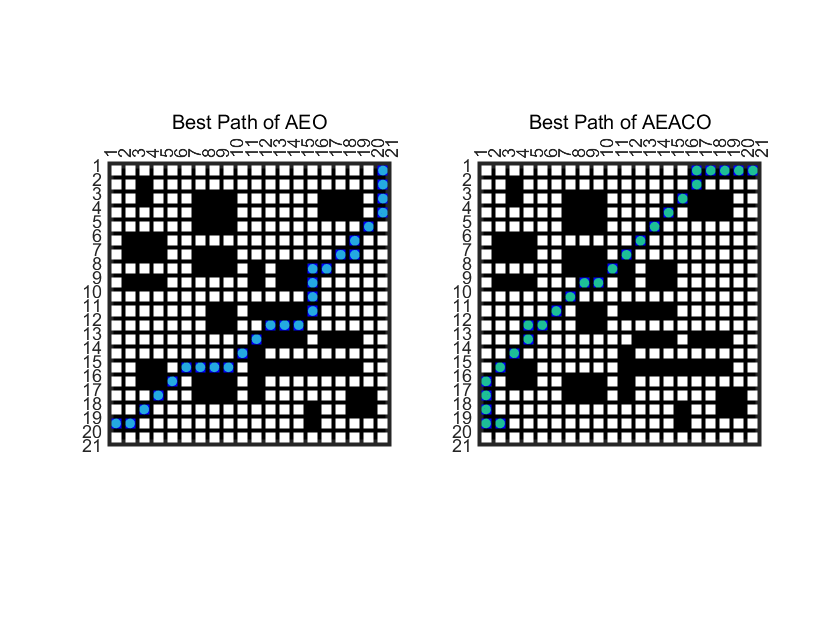

%%draw pic
figure(1)
colormap(color_map);
subplot(1,2,1)
fisrt_inf_ind = find(isinf(path_best1(1,:)),1);
path_best1 = path_best1(1:fisrt_inf_ind-1);
field(path_best1(2:end-1)) = 5;
image(1.5,1.5,field);
hold on;
grid on;
set(gca,'gridline','-','GridColor','k','LineWidth',2,'GridAlpha',1);
set(gca,'XTick',1:column_map+1,'YTick',1:row_map+1);
set(gca,'XAxisLocation','top')
axis image
for i = 1:length(path_best1)-1
    [coord1_x,coord1_y] = ind2sub([row_map,column_map],path_best1(i));
    [coord2_x,coord2_y] = ind2sub([row_map,column_map],path_best1(i+1));
    plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'ok-', 'linewidth', 1.1,'linestyle','-','Color','b','markerfacecolor', [36, 169, 225]/255)
    %这里的coord1_x应该是对应的y
end
hold off;
title('Best Path of AEO')

colormap(color_map);
subplot(1,2,2)
fisrt_inf_ind = find(isinf(path_best2(1,:)),1);
path_best2 = path_best2(1:fisrt_inf_ind-1);
field_copy(path_best2(2:end-1)) = 5;
image(1.5,1.5,field_copy);
grid on;
set(gca,'gridline','-','GridColor','k','LineWidth',2,'GridAlpha',1);
set(gca,'XTick',1:column_map+1,'YTick',1:row_map+1);
set(gca,'XAxisLocation','top')
axis image
hold on
for i = 1:length(path_best2)-1
    [coord1_x,coord1_y] = ind2sub([row_map,column_map],path_best2(i));
    [coord2_x,coord2_y] = ind2sub([row_map,column_map],path_best2(i+1));
    plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'ok-', 'linewidth', 1.1, 'linestyle','-','Color','b','markerfacecolor', [29, 191, 151]/255);
    %这里的coord1_x应该是对应的y
end
hold off;
title('Best Path of AEACO')

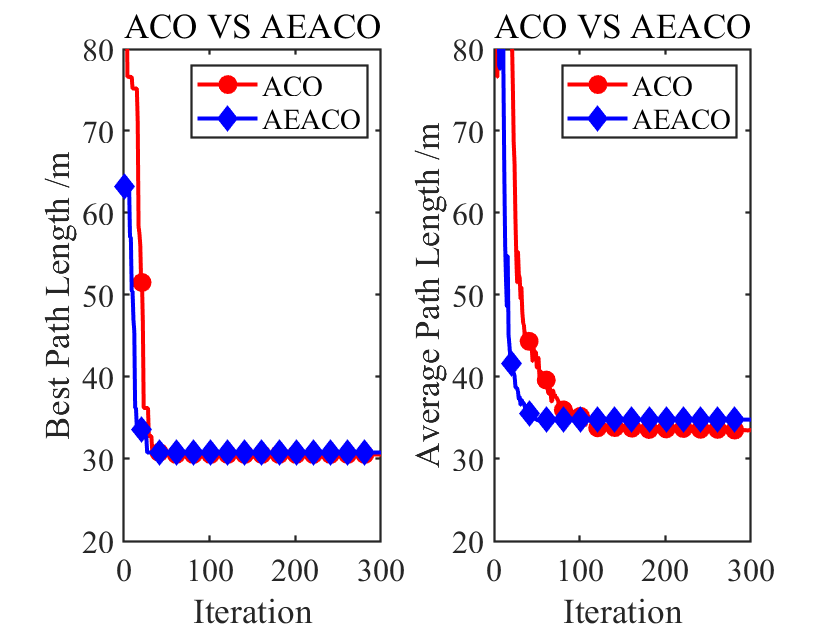

figure(2)
%平均值会出现一些inf不好比较
maker_idx = 1:20:length(per_iter_avg1);
subplot(1,2,1)
plot(per_iter_best1, 'or-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'r','MarkerIndices',maker_idx)
hold on
plot(per_iter_best2, 'db-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'b','MarkerIndices',maker_idx)
xlabel('Iteration')
ylabel('Best Path Length /m');
legend('ACO','AEACO');
axis([0, 300, 20 80])
set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')
title('ACO VS AEACO')
subplot(1,2,2)
plot(per_iter_avg1, 'or-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'r','MarkerIndices',maker_idx)
hold on
plot(per_iter_avg2, 'db-', 'linewidth', 2, 'markersize',7.5,'MarkerfaceColor', 'b','MarkerIndices',maker_idx)
xlabel('Iteration')
ylabel('Average Path Length /m');
legend('ACO','AEACO');
axis([0, 300, 20 80])
set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')
title('ACO VS AEACO')

#### **计算转角次数**

numb_turn_org = 0;
numb_turn_prob = 0;
for j = 1:length(path_best1)-2
    ind1 = path_best1(j);
    ind2 = path_best1(j+1);
    ind3 = path_best1(j+2);
    [ind1_sub(1),ind1_sub(2)] = ind2sub([20,20],ind1);
    [ind2_sub(1),ind2_sub(2)] = ind2sub([20,20],ind2);
    [ind3_sub(1),ind3_sub(2)] = ind2sub([20,20],ind3);
    if (ind3_sub(2)-ind2_sub(2))/(ind3_sub(1)-ind2_sub(1)) ~= ...
        (ind1_sub(2)-ind2_sub(2))/(ind1_sub(1)-ind2_sub(1))
        numb_turn_org = numb_turn_org+1;
    end
end
for j = 1:length(path_best2)-2
    ind1 = path_best2(j);
    ind2 = path_best2(j+1);
    ind3 = path_best2(j+2);
    [ind1_sub(1),ind1_sub(2)] = ind2sub([20,20],ind1);
    [ind2_sub(1),ind2_sub(2)] = ind2sub([20,20],ind2);
    [ind3_sub(1),ind3_sub(2)] = ind2sub([20,20],ind3);
    if (ind3_sub(2)-ind2_sub(2))/(ind3_sub(1)-ind2_sub(1)) ~= ...
        (ind1_sub(2)-ind2_sub(2))/(ind1_sub(1)-ind2_sub(1))
        numb_turn_prob = numb_turn_prob+1;
    end
end
alpha = abs(dist_best2-dist_best1)/dist_best1;
beta = -(numb_turn_prob-numb_turn_org)/numb_turn_org; %>0表示改进算法更优秀
